# Adaptive control for linear systems

## Simulation data generation

sqareWaveGen = @(t, T)((t - T*floor(t/T)) < T/2);

H = tf(2, [1 3 1]);
Te = 0.1;
Hd = c2d(H, Te, 'zoh');
H0 = feedback(Hd, 1);

[num, den] = tfdata(H0, 'v');
T = 30*Te;
t = 0:Te:6*T;
u = sqareWaveGen(t, T);

## Initialization

% system polynomial orders
na = 2;
nb = 1;
nd = 1;
windowSize = 50; % observation vector and measurements size
wIdx = 1;
window = zeros(na + nb + 1, 1); 
inputBuffer = zeros(nd, 1);
outputBuffer = zeros(1, 1);
wY = zeros(windowSize, 1); % measurements
phi = zeros(nb + na + 1, windowSize); % observation vector

% Optimizer utility functions
evalGradient = @(theta, phi, y)(-2*sum((y - theta'*phi).*phi, 2));
evalHessian = @(phi)(2*phi*phi');
evalCost = @(theta, phi, y)(sum((y - theta'*phi).^2));
alpha = 1; % optimizer step
beta = 1.1; % bactracking step increment
alphaUpperThreshold = 10000; % step upper boundary
alphaBottomTreshold = 0.000001; % step bottom boundary

% paramters to optimize
theta = [num(2:end)'; den(2:end)'];
theta = [theta theta];

% non-zero intial conditions avoidance
timeUnitsToWait = max(nb + nd, na);
timeUnitsWaited = 0;
isReady = false;

% simulation models
q0 = 1/sum(num);
Hcd = tf(q0*den, [1 -q0*num(2:end)], Te)

Hcd =
 
  57.92 z^2 - 99.81 z + 43.39
  ---------------------------
     z^2 - 0.525 z - 0.475
 
Sample time: 0.1 seconds
Discrete-time transfer function.




system = DiscreteModelZoh(num(2:end), den(2:end))

system =   DiscreteModelZoh with properties:

      u: [2×1 double]
      y: [2×1 double]
    num: [0.0091 0.0082]
    den: [-1.7231 0.7490]



controller = DiscreteModel(q0*den, -q0*num(2:end));
m = floor(length(u)/2);
aux = m;

output = zeros(length(u), 1);
command = zeros(length(u), 1);
error = zeros(length(u), 1);

error(1) = u(1);

## Algorithm implemetation

% Loop
for i = 1:length(u)-1
    % measurements and observation vector update
    tic
    [controller, command(i), ~] = forward(controller, error(i));
    [system, output(i), res] = forward(system, command(i));
    error(i + 1) = u(i + 1) - res;
    
    if i == floor(length(u)/8)
        change = normrnd(theta(:, 2), 0.002);
        system.num = change(1:2)';
        system.den = change(3:end)';
        changeTime = t(i);
        m = m + aux;
    end
    
    if nd >= 1
        window(1) = inputBuffer(1);
    else
        window(1) = command(i);
    end
    for j = 2:nb+1
        if wIdx - 1 >= 1
            window(j) = phi(j - 1, wIdx - 1);
        end
    end
    if nd > 1 
        inputBuffer(1:end-1) = inputBuffer(2:end);
        inputBuffer(end) = command(i);
    else
        inputBuffer = command(i);
    end
    
    window(nb + 2) = -outputBuffer;
    for k = nb+3:nb+1+na
        if wIdx - 1 >= 1
            window(k) = phi(k - 1, wIdx - 1);
        end
    end
    outputBuffer = output(i);
    
    if wIdx <= windowSize
        phi(:, wIdx) = window;
        wY(wIdx) = output(i);
        idx = wIdx;
        wIdx = wIdx + 1;
    else
        phi = [phi(:, 2:end) window];
        wY = [wY(2:end); output(i)];
    end
    
    if isReady == false && timeUnitsWaited >= timeUnitsToWait
        isReady = true;
        phi = [phi(:, timeUnitsToWait+1:end) zeros(nb + na + 1, timeUnitsToWait)];
        wY = [wY(timeUnitsToWait+1:end); zeros(timeUnitsToWait, 1)];
        wIdx = 2;
        idx = 1;
    end
    
    if isReady == false
        timeUnitsWaited = timeUnitsWaited + 1;
    else
         % AAP
        gradient = evalGradient(theta(:, 1), phi(:, 1:idx), wY(1:idx)');
        if norm(gradient) ~= 0 
            gradient = gradient/norm(gradient);
            if rank(phi(:, 1:idx)) == na + nb + 1
                hessian = evalHessian(phi(:, 1:idx));
                hessian = hessian/norm(hessian);
                optimizerDirection = hessian\gradient;
            else
                optimizerDirection = gradient;
            end
           
            theta(:, 2) = theta(:, 1) - optimizerDirection*alpha;
            cost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
            newAlpha = beta*alpha;
            theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
            newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
            
            if newCost < cost
                while newCost < cost && newAlpha < alphaUpperThreshold
                    cost = newCost;
                    newAlpha = beta*newAlpha;
                    theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                    newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
                end
                newAlpha = newAlpha/beta;
                theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
            else
                newAlpha = alpha/beta;
                theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
                
                if newCost < cost 
                    while newCost < cost && newAlpha > alphaBottomTreshold
                        cost = newCost;
                        newAlpha = newAlpha/beta;
                        theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                        newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
                    end
                    newAlpha = newAlpha*beta;
                    theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                else
                    theta(:, 2) = theta(:, 1) - optimizerDirection*alpha;
                end
            end
            theta(:, 1) = theta(:, 2);
        end
        
        num = [0 theta(1:nb+1, 1)'];
        den = [1 theta(nb+2:nb+1+na, 1)'];
        q0 = 1/sum(num);
        controller.den = -q0*num(2:end);
        controller.num = q0*den;
    end
    toc
end

Elapsed time is 0.004482 seconds.
Elapsed time is 0.002828 seconds.
Elapsed time is 0.006642 seconds.
Elapsed time is 0.003404 seconds.
Elapsed time is 0.017613 seconds.
Elapsed time is 0.001178 seconds.
Elapsed time is 0.001189 seconds.
Elapsed time is 0.000198 seconds.
Elapsed time is 0.000781 seconds.
Elapsed time is 0.000111 seconds.
Elapsed time is 0.000102 seconds.
Elapsed time is 0.000105 seconds.
Elapsed time is 0.000088 seconds.
Elapsed time is 0.000084 seconds.
Elapsed time is 0.000082 seconds.
Elapsed time is 0.000081 seconds.
Elapsed time is 0.000082 seconds.
Elapsed time is 0.000082 seconds.
Elapsed time is 0.000083 seconds.
Elapsed time is 0.000082 seconds.
Elapsed time is 0.000082 seconds.
Elapsed time is 0.007012 seconds.
Elapsed time is 0.007932 seconds.
Elapsed time is 0.002106 seconds.
Elapsed time is 0.001637 seconds.
Elapsed time is 0.001602 seconds.
Elapsed time is 0.007597 seconds.
Elapsed time is 0.001316 seconds.
Elapsed time is 0.001090 seconds.
Elapsed time i

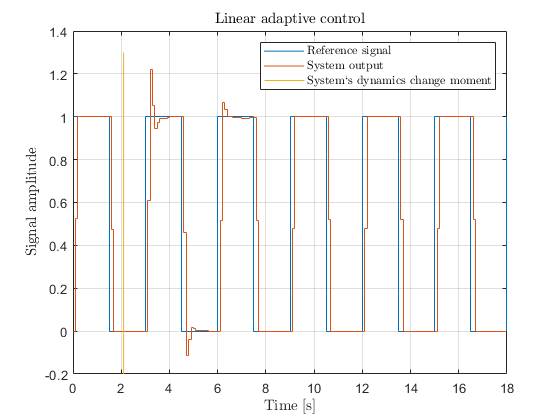


figure,
stairs(t, u);
hold on;
stairs(t, output); grid;
xline = -0.2:0.1:1.3;
yline = changeTime*ones(length(xline), 1);
plot(yline, xline);

title("Linear adaptive control", "Interpreter", "Latex");
xlabel("Time [s]", "Interpreter", "latex");
ylabel("Signal amplitude", "Interpreter", "latex");
legend("Reference signal", "System output", "System`s dynamics change moment", "Interpreter", "Latex");